clear;
clc;
N = 50000; % Number of points
a = 0;     % initial abscissa
b = 0;     % initial ordinate
m = 1;     % Section ratio (m:n)
n = 1;
x = zeros(1,N);
y = zeros(1,N);
x(1)=a;
y(1)=b;
z = randi([1,3],1,N)

z =      3     2     3     3     2     2     1     3     1     1     1     1     1     2     1     1     1     2     1     3     2     2     1     3     2     3     1     2     2     2     2     2     2     2     3     1     3     1     3     3     3     3     3     1     3     1     1     1     3     1


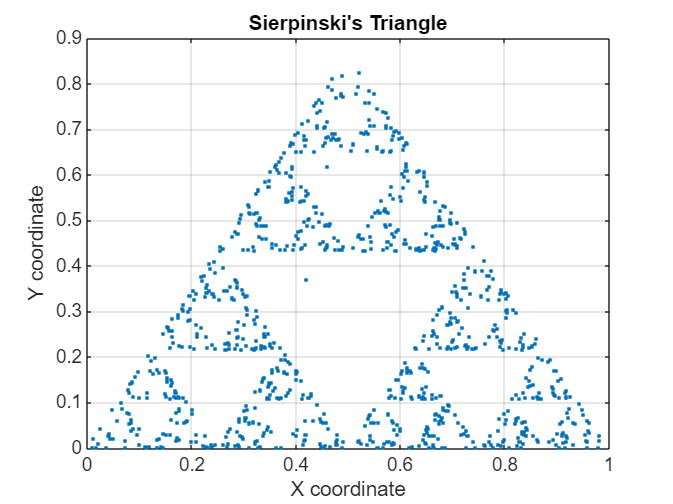

for i=2:N
    if(z(i)==1)
        x(i) = m*x(i-1)/(m+n);
        y(i) = m*y(i-1)/(m+n);
    else 
        if(z(i)==2)
            x(i) = (m*x(i-1)+n)/(m+n);
            y(i) = (m*y(i-1))/(m+n);
        else
            x(i) = (m*x(i-1)+0.5*n)/(m+n);
            y(i) = (m*y(i-1)+0.866*n)/(m+n);
        end
    end
end

plot(x,y,'.')
xlabel("X coordinate")
ylabel("Y coordinate")
title("Sierpinski's Triangle")
grid on